## Robot Visualizer Example: Basics and Waypoints

Copyright 2018 The MathWorks, Inc.

Create a `Visualizer2D` object.

viz = Visualizer2D;

Display a robot in the empty world at a specified pose.  

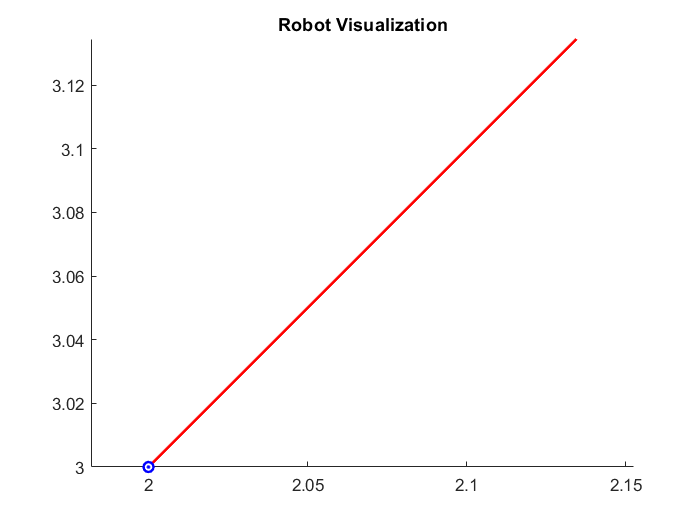

pose = [2; 3; pi/4];
viz(pose)

Add waypoints to the visualization. This requires setting the `hasWaypoints`property to `true`, as well as specifying an additional input as rows of `[x y]` coordinates.

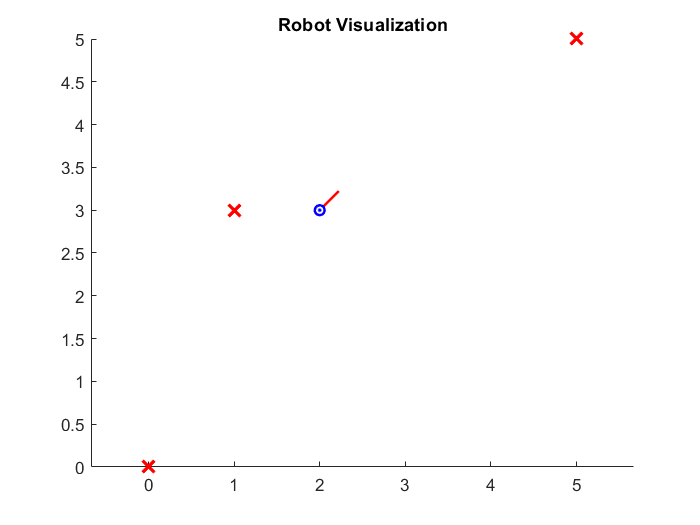

release(viz) % Needed if changing hasWaypoints property after visualizing
waypoints = [0, 0; 5, 5; 1, 3];
viz.hasWaypoints = true;
viz(pose,waypoints);

Move the robot randomly 10 times and update the visualization.

**NOTE:** If you run this section in a plain code script, this section will be animated.

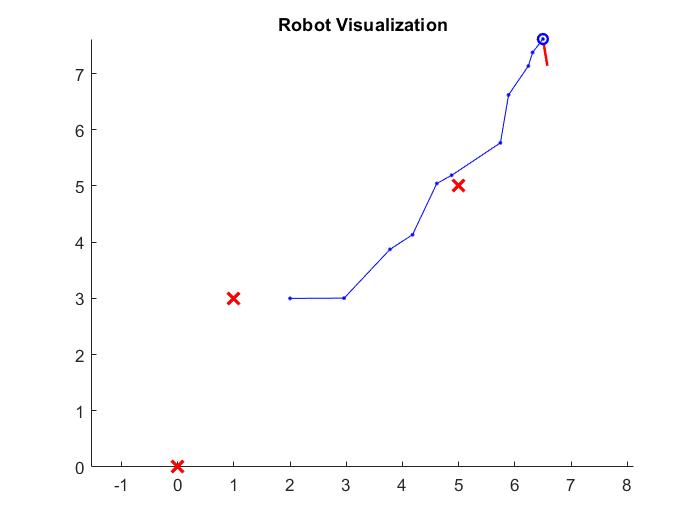

for idx = 1:10
    pose = pose + rand(3,1);
    viz(pose,waypoints)
    pause(0.25)
end